#### HW2-SPECTRAL CLUSTERING

POLITECNICO DI TORINO-ELISA SALVADORI (302630)

close all
clear
clc
rng('default')

**Circle**

Loading the Circle dataset

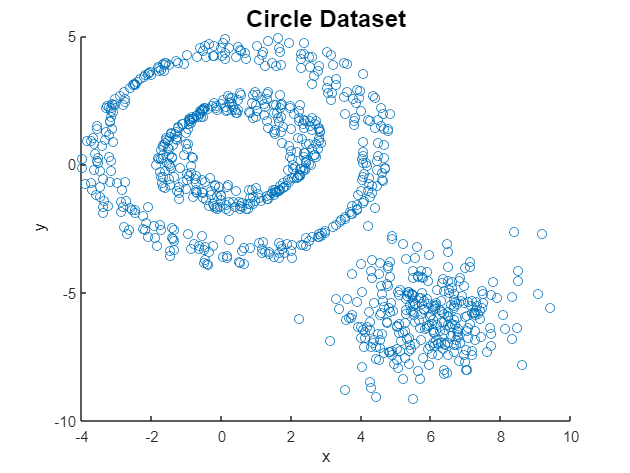

%Circle

Circle = load('Circle.mat');
X = (Circle.X);
Xt = X';

N = size(Xt, 2);

scatter(X(:,1), X(:,2)); 
title('Circle Dataset', 'FontSize', 16);           
xlabel('x')
ylabel('y')

# Exercise 1

All the exercise need to be computed with different values of k (number of points for k-nearest neighborhood). **Uncomment the desired value of k for the computation (and comment the others).**

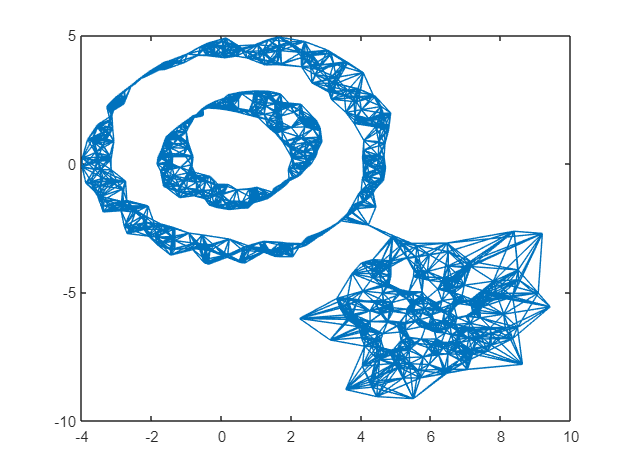

sigma = 1; %Setting the value of sigma

%%%%%%% VALUES OF K %%%%%%%

 k = 10;
% k = 20;
% k = 40;

%%%%%%%%%%%%%%%%%%%%%%%%%%%

norm2 = @(X) (X(1, :).* X(1, :) + X(2, :).* X(2, :)); %Defining a function for the computation of the square of the norm2
similarity = @(X1, X2, sigma) exp(-norm2(X2 - X1)./2*sigma^2); %Defining the function for the computation of the similarity function

%Computing the adjancency matrix W

W = spalloc(N, N, N*k*2); %creates an N-by-N all zero sparse matrix with room to eventually hold N*k*2 nonzeros

%Evaluating the similarity function for each point and taking only the k largest values 

for i = 1:N
    s_ij = similarity(Xt(:, i), Xt, sigma);
    [vals, idx] = maxk(s_ij, k+1); %Taking the indeces of the k points with 
    %the largest values of similiraty function with 
    %point i, k+1 is beacause we are taking also the point itself, 
    %taking also the values
    W(i, idx(idx ~= i)) = vals(idx ~= i); %Setting W
    W(idx(idx ~= i), i) = vals(idx ~= i); %W is a symmetric matrix with zeros on the diagonal
end

%Plotting the k-nearest neighborhood similarity graph
figure
gplot(W, X)

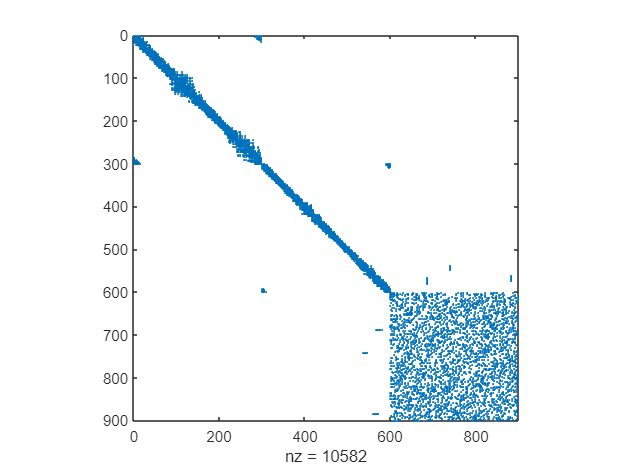

%Plotting the sparsity pattern of W.
figure
spy(W)

# Exercise 2

%Construction of degree matrix D
d = sum(W, 2);
D = diag(d);

%Construction of Laplacian matrix L
L = D - W;

%With the command Sparse it is possible to store L, D, W in sparse format
%and so saving memory.

# Exercise 3

%Computing the number of connected components of the similarity graph.

[eigV, eigD] = eigs(L, 10, 'smallestabs'); %Computing the 10 smallest eigenvalues and corresponding eigenvectors

eigD = diag(eigD);
[eigD, IJ] = sort(eigD); %Sorting the eigenvalues
eigV = eigV(:, IJ); %Sorting eigenvectors

number_connected_components = sum(eigD < 1.0e-6); %The number of eigenvalues smaller than 10^(-6) is the number of connected components

s = sprintf("The graph has %d connected components", number_connected_components);
disp(s)

The graph has 2 connected components


# Exercise 4

%Computing some small eigenvalues of L and using their values to choose a suitable number of clusters M for the points data-sets.

eigD

eigD =     0.0000
    0.0000
    0.0048
    0.0286
    0.0425
    0.0429
    0.0806
    0.1264
    0.1349
    0.2092


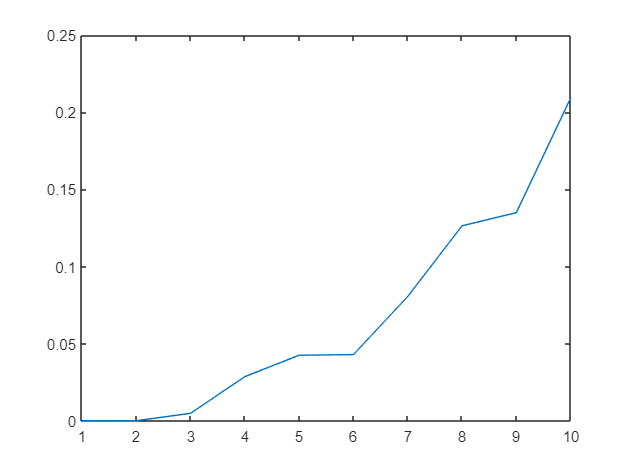

figure
plot(eigD)

A suitable number of clusters is equal to the number of eigenvalues relatively small. 

# Exercise 5

Running the algorithm for different values of k, the number of clusters is M = 3, 2, 2 for k = 10, 20, 40 respectively.** Uncomment M  = 2 for the computation with other k and comment M = 3.**

%%%%%%% VALUES OF M %%%%%%%

 M = 3; %Number of searched clusters
% M = 2; %Number of searched clusters 

%%%%%%%%%%%%%%%%%%%%%%%%%%%

[eigV, eigD] = eigs(L, M, 'smallestabs'); %Computing M eigenvectors corresponding to the smallest M eigenvalues

U = eigV;

# Exercise 6

%Definition of clusters colors
markers(1, :) = 'ro';
markers(2, :) = 'bx';
markers(3, :) = 'g*';
markers(4, :) = 'cs';
markers(5, :) = 'md';
markers(6, :) = 'rx';
markers(7, :) = 'bs';
markers(8, :) = 'gd';
markers(9, :) = 'c*';
markers(10, :) = 'mx';

idx = kmeans(U, M); %Getting the index of the cluster for each point

# Exercise 7

%Assigning the original points to the same cluster as their corresponding
%rows in U

A = cell(1,M);

for i = 1:M
    A{i} = [Xt(1, idx == i); Xt(2, idx == i)];
end

# Exercise 8 

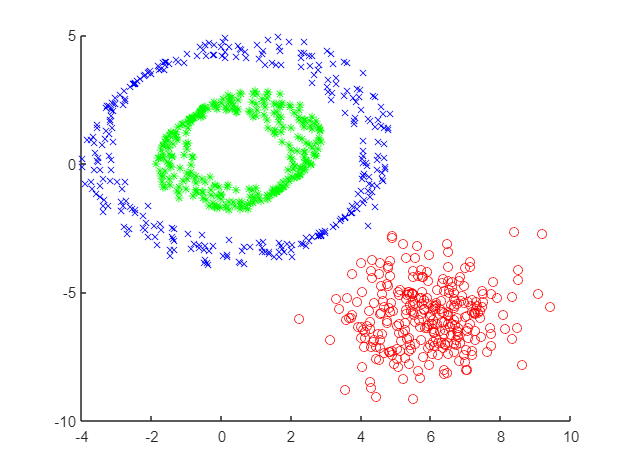

%Plotting the resulting clustered points

figure 
hold on
for i = 1:M
    plot(Xt(1, idx == i), Xt(2, idx == i), markers(i, :))
end

# Exercise 9

Computing the clusters with other clustering methos from library.

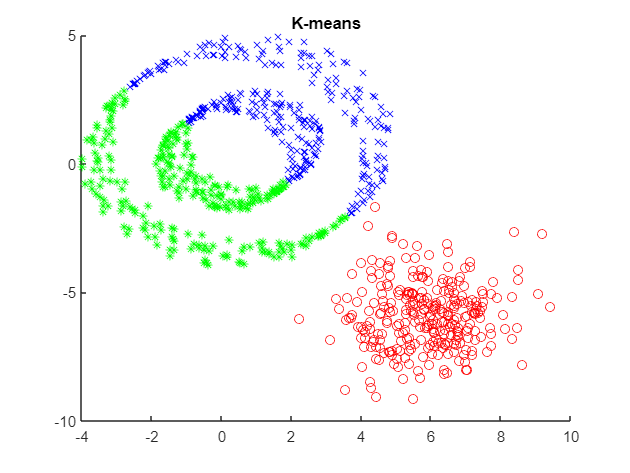

%K-means 

idx_km = kmeans(X, M);

figure
hold on 
for i = 1:M
    plot(Xt(1, idx_km == i), Xt(2, idx_km == i), markers(i, :))
end
title('K-means')

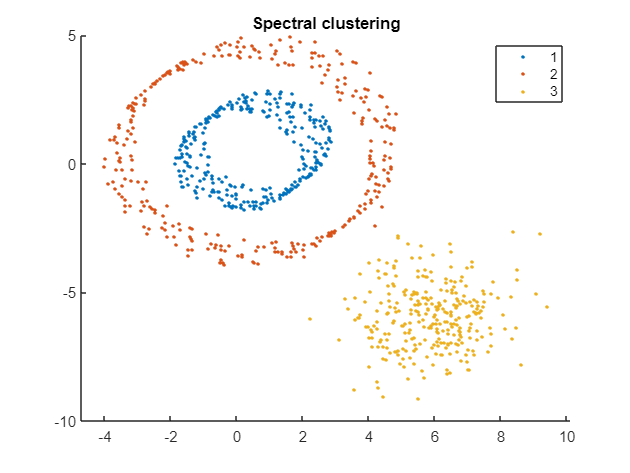

%Spectral clustering 

idx_sc = spectralcluster(X, M, 'SimilarityGraph', 'knn', 'NumNeighbors', k); 

figure
hold on
gscatter(Xt(1,:), Xt(2,:), idx_sc)
title('Spectral clustering')

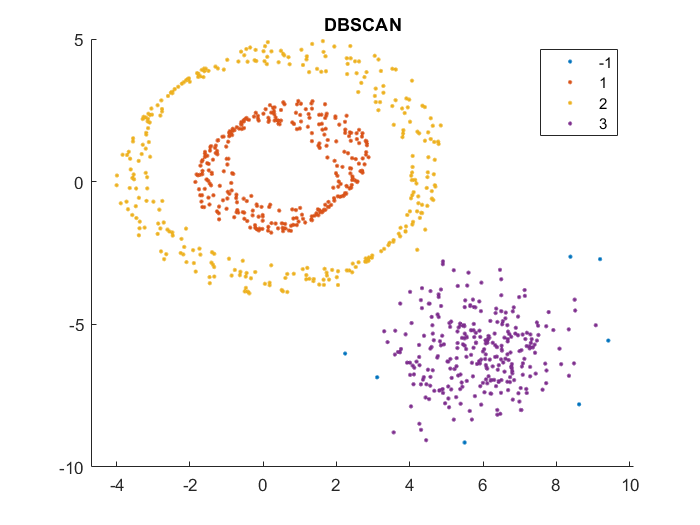

%DBSCAN:

idx_db = dbscan(X,0.8,5); 

figure
hold on           
gscatter(Xt(1,:), Xt(2,:), idx_db);
title('DBSCAN')

close all
clear
clc
rng('default')

**Spiral**

Loading the Spiral dataset

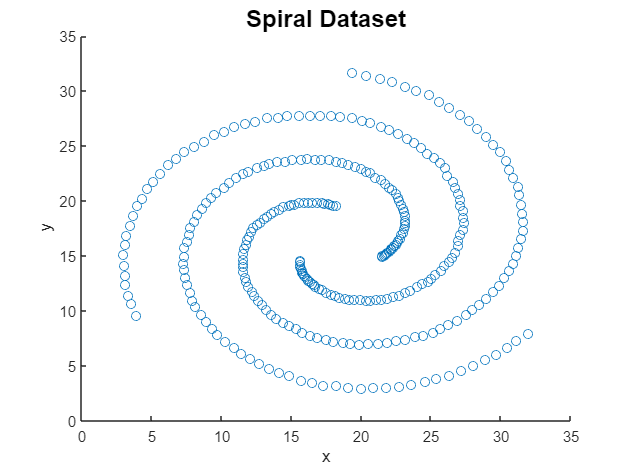

%Spiral

Spiral = load('Spiral.mat');
X = (Spiral.X(:, 1:2)); %Only taking the first and second colmuns (the third one is the label)
Xt = X';

N = size(Xt, 2);

scatter(X(:,1), X(:,2)); 
title('Spiral Dataset', 'FontSize', 16);           
xlabel('x')
ylabel('y')

# Exercise 1

All the exercise need to be computed with different values of k (number of points for k-nearest neighborhood). **Uncomment the desired value of k for the computation (and comment the others).**

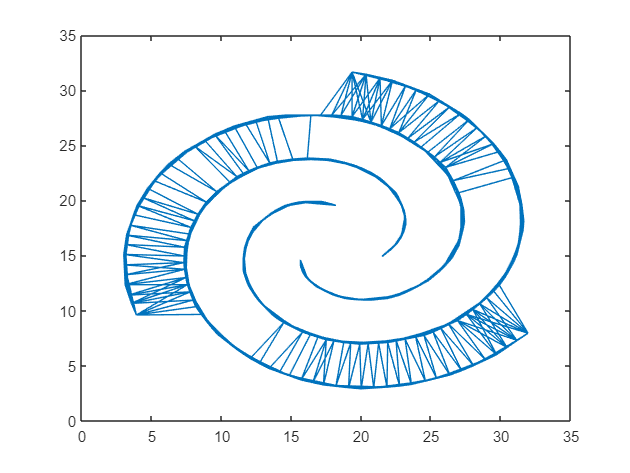

sigma = 1; %Setting the value of sigma

%%%%%%% VALUES OF K %%%%%%%

 k = 10;
% k = 20;
% k = 40;

%%%%%%%%%%%%%%%%%%%%%%%%%%%

norm2 = @(X) (X(1, :).* X(1, :) + X(2, :).* X(2, :)); %Defining a function for the computation of the square of the norm2
similarity = @(X1, X2, sigma) exp(-norm2(X2 - X1)./2*sigma^2); %Defining the function for the computation of the similarity function

%Computing the adjancency matrix W

W = spalloc(N, N, N*k*2); %creates an N-by-N all zero sparse matrix with room to eventually hold N*k*2 nonzeros

%Evaluating the similarity function for each point and taking only the k largest values 

for i = 1:N
    s_ij = similarity(Xt(:, i), Xt, sigma);
    [vals, idx] = maxk(s_ij, k+1); %Taking the indeces of the k points with 
    %the largest values of similiraty function with 
    %point i, k+1 is beacause we are taking also the point itself, 
    %taking also the values
    W(i, idx(idx ~= i)) = vals(idx ~= i); %Setting W
    W(idx(idx ~= i), i) = vals(idx ~= i); %W is a symmetric matrix with zeros on the diagonal
end

%Plotting the k-nearest neighborhood similarity graph
figure
gplot(W, X)

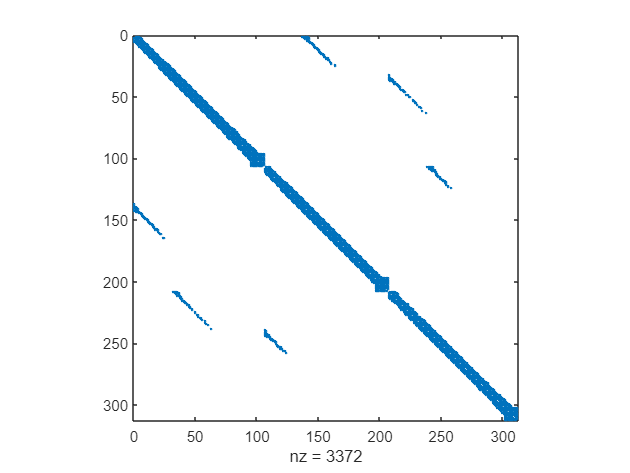

%Plotting the sparsity pattern of W.
figure
spy(W)

# Exercise 2

%Construction of degree matrix D
d = sum(W, 2);
D = diag(d);

%Construction of Laplacian matrix L
L = D - W;

# Exercise 3

%Computing the number of connected components of the similarity graph.

[eigV, eigD] = eigs(L, 10, 'smallestabs'); %Computing the 10 smallest eigenvalues and corresponding eigenvectors

eigD = diag(eigD);
[eigD, IJ] = sort(eigD); %Sorting the eigenvalues
eigV = eigV(:, IJ); %Sorting eigenvectors

number_connected_components = sum(eigD < 1.0e-6); %The number of eigenvalues smaller than 10^(-6) is the number of connected components

s = sprintf("The graph has %d connected components", number_connected_components);
disp(s)

The graph has 1 connected components


# Exercise 4

%Computing some small eigenvalues of L and using their values to choose a suitable number of clusters M for the points data-sets.

eigD

eigD =     0.0000
    0.0002
    0.0003
    0.0041
    0.0044
    0.0046
    0.0172
    0.0184
    0.0189
    0.0404


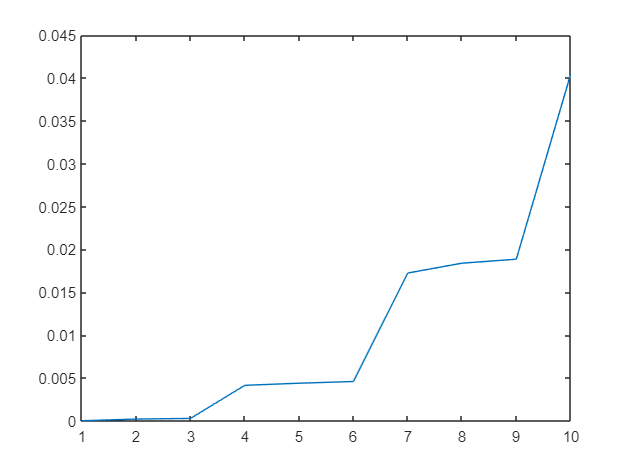

figure
plot(eigD)

A suitable number of clusters is equal to the number of eigenvalues relatively small. 

# Exercise 5

Running the algorithm for different values of k, the number of clusters is M = 3, 3, 6  for k = 10, 20, 40 respectively.** Uncomment  M =  6 for the computation with the other k and comment M = 3.**

%%%%%%% VALUES OF M %%%%%%%

 M = 3; %Number of searched clusters
% M = 6; %Number of searched clusters 

%%%%%%%%%%%%%%%%%%%%%%%%%%%

[eigV, eigD] = eigs(L, M, 'smallestabs'); %Computing M eigenvectors corresponding to the smallest M eigenvalues

U = eigV;

# Exercise 6

%Definition of clusters colors
markers(1, :) = 'ro';
markers(2, :) = 'bx';
markers(3, :) = 'g*';
markers(4, :) = 'cs';
markers(5, :) = 'md';
markers(6, :) = 'rx';
markers(7, :) = 'bs';
markers(8, :) = 'gd';
markers(9, :) = 'c*';
markers(10, :) = 'mx';

idx = kmeans(U, M); %Getting the index of the cluster for each point

# Exercise 7

%Assigning the original points to the same cluster as their corresponding
%rows in U

A = cell(1,M);

for i = 1:M
    A{i} = [Xt(1, idx == i); Xt(2, idx == i)];
end

# Exercise 8 

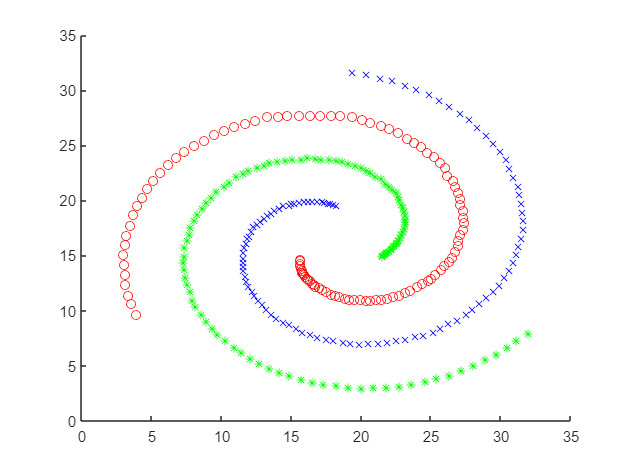

%Plotting the resulting clustered points

figure 
hold on
for i = 1:M
    plot(Xt(1, idx == i), Xt(2, idx == i), markers(i, :))
end

# Exercise 9

Computing the clusters with other clustering methos from library.

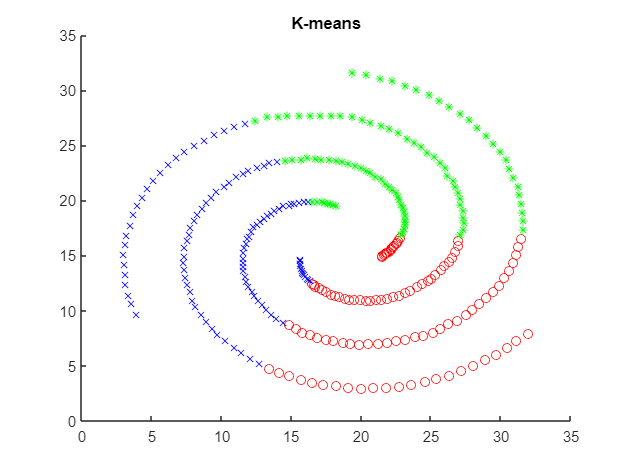

%K-means 

idx_km = kmeans(X, M);

figure
hold on 
for i = 1:M
    plot(Xt(1, idx_km == i), Xt(2, idx_km == i), markers(i, :))
end
title('K-means')

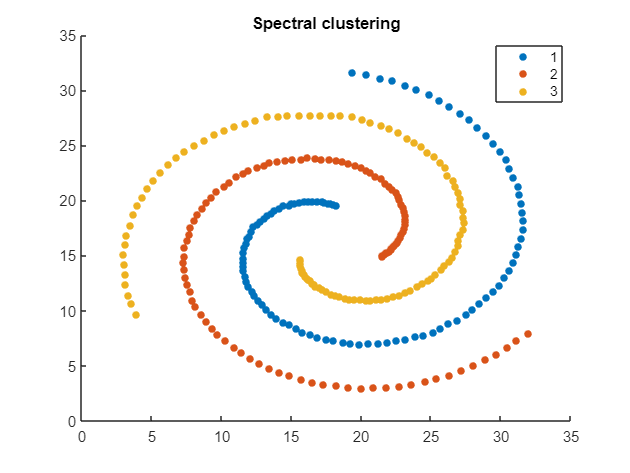

%Spectral clustering 

idx_sc = spectralcluster(X, M, 'SimilarityGraph', 'knn', 'NumNeighbors', k);

figure
hold on
gscatter(Xt(1,:), Xt(2,:), idx_sc)
title('Spectral clustering')

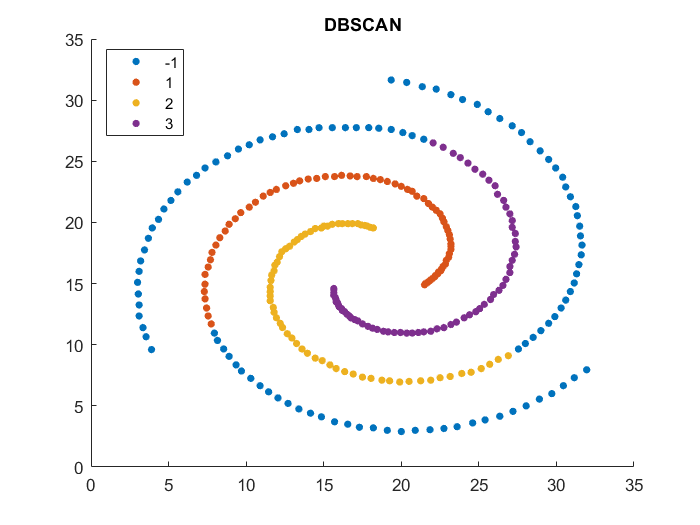

%DBSCAN:

idx_db = dbscan(X, 2, 6); 

figure
hold on          
gscatter(Xt(1,:), Xt(2,:), idx_db);
title('DBSCAN')

close all
clear
clc
rng('default')

### **OPTIONAL POINT (3D DATASET)**

Creating 3D dataset.

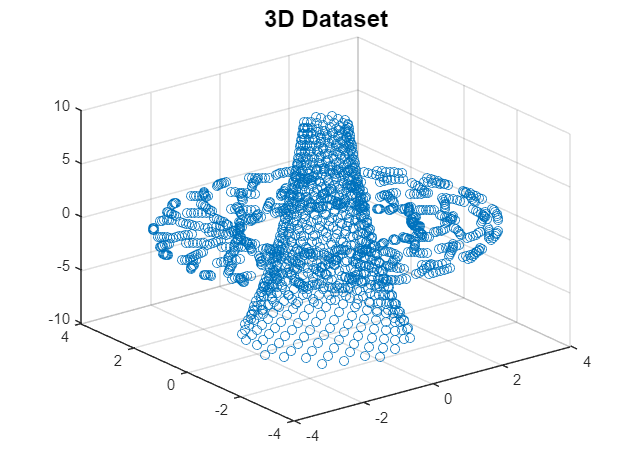

t1 = linspace(0, 40*pi, 900);

xt1 = (3 + cos(sqrt(32)*t1)).*cos(t1);
yt1 = sin(sqrt(32) * t1);
zt1 = (3 + cos(sqrt(32)*t1)).*sin(t1);


angle = atan(sqrt(32));
R = [1 0 0; 0 cos(angle) -sin(angle); 0 sin(angle) cos(angle)];
new_data = R * [xt1; yt1; zt1];

xt1 = new_data(1,:);
yt1 = new_data(2,:);
zt1 = new_data(3,:);


t2 = linspace(-10,10, 800); 

xt2 = exp(-t2./15).*sin(30*t2);
yt2 = exp(-t2./15).*cos(30*t2);
zt2 = t2;

xt = [xt1, xt2]';
yt = [yt1, yt2]';
zt = [zt1, zt2]';


X = [xt, yt, zt];
Xt = X';
N = size(Xt, 2);

scatter3(xt, yt, zt,'o')
title('3D Dataset', 'FontSize', 16)

# Exercise 1

All the exercise need to be computed with different values of k (number of points for k-nearest neighborhood). **Uncomment the desired value of k for the computation (and comment the others).**

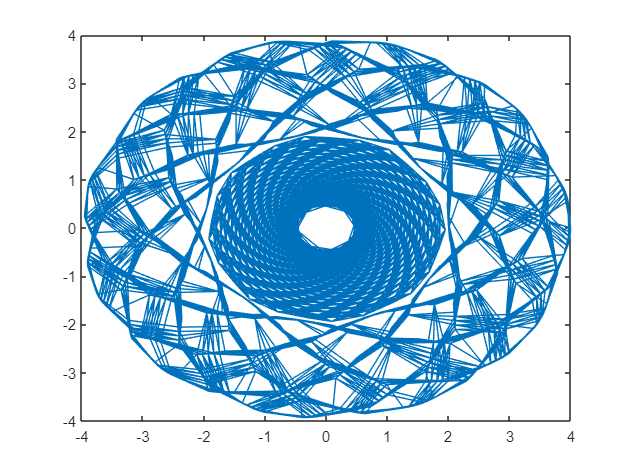

sigma = 1; %Setting the value of sigma

%%%%%%% VALUES OF K %%%%%%%

 k = 10;
% k = 20;
% k = 40;

%%%%%%%%%%%%%%%%%%%%%%%%%%%

norm2 = @(X) (X(1, :).* X(1, :) + X(2, :).* X(2, :) + X(3, :).* X(3, :)); %Defining a function for the computation of the square of the norm2
similarity = @(X1, X2, sigma) exp(-norm2(X2 - X1)./2*sigma^2); %Defining the function for the computation of the similarity function

%Computing the adjancency matrix W

W = spalloc(N, N, N*k*2); %creates an N-by-N all zero sparse matrix with room to eventually hold N*k*2 nonzeros

%Evaluating the similarity function for each point and taking only the k largest values 

for i = 1:N
    s_ij = similarity(Xt(:, i), Xt, sigma);
    [vals, idx] = maxk(s_ij, k+1); %Taking the indeces of the k points with 
    %the largest values of similiraty function with 
    %point i, k+1 is beacause we are taking also the point itself, 
    %taking also the values
    W(i, idx(idx ~= i)) = vals(idx ~= i); %Setting W
    W(idx(idx ~= i), i) = vals(idx ~= i); %W is a symmetric matrix with zeros on the diagonal
end

%Plotting the k-nearest neighborhood similarity graph
figure
gplot(W, X)

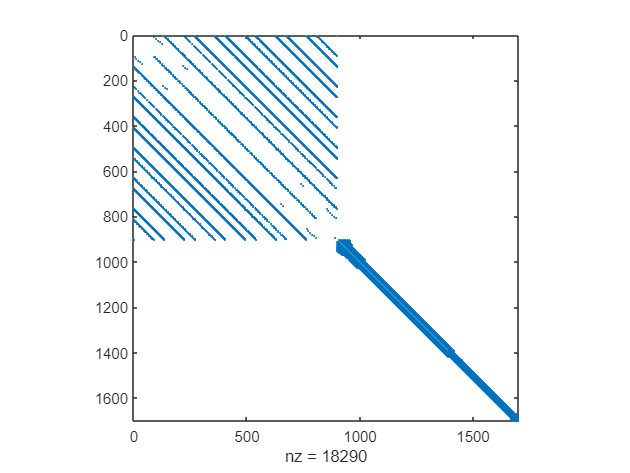

%Plotting the sparsity pattern of W.
figure
spy(W)

# Exercise 2

%Construction of degree matrix D
d = sum(W, 2);
D = diag(d);

%Construction of Laplacian matrix L_sym
L = (D^(-.5)) * (D - W) * (D^(-.5));

# Exercise 3

%Computing the number of connected components of the similarity graph.

[eigV, eigD] = eigs(L, 10, 'smallestabs'); %Computing the 10 smallest eigenvalues and corresponding eigenvectors

eigD = diag(eigD);
[eigD, IJ] = sort(eigD); %Sorting the eigenvalues
eigV = eigV(:, IJ); %Sorting eigenvectors

number_connected_components = sum(eigD < 1.0e-6); %The number of eigenvalues smaller than 10^(-6) is the number of connected components

s = sprintf("The graph has %d connected components", number_connected_components);
disp(s)

The graph has 2 connected components


# Exercise 4

%Computing some small eigenvalues of L and using their values to choose a suitable number of clusters M for the points data-sets.

eigD

eigD =    -0.0000
   -0.0000
    0.0016
    0.0059
    0.0077
    0.0078
    0.0143
    0.0246
    0.0287
    0.0292


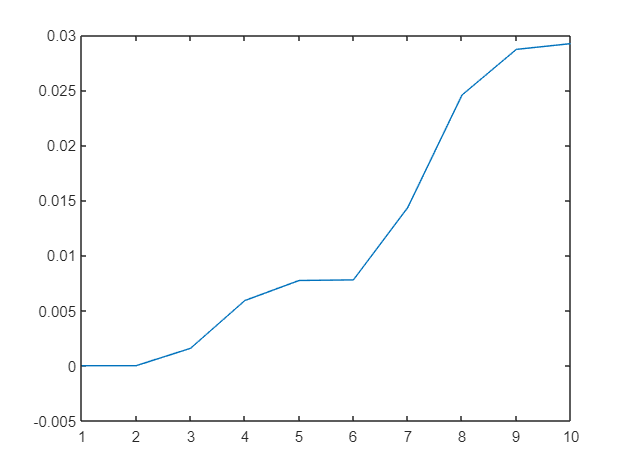

figure
plot(eigD)

A suitable number of clusters is equal to the number of eigenvalues relatively small. 

# Exercise 5

Running the algorithm for different values of k, the number of clusters is M = 3, 3, 2  for k = 10, 20, 40 respectively.** Uncomment  M =  2 for the computation with the other k and comment M = 3.**

%%%%%%% VALUES OF M %%%%%%%

 M = 3; %Number of searched clusters
% M = 2; %Number of searched clusters 

%%%%%%%%%%%%%%%%%%%%%%%%%%%

[eigV, eigD] = eigs(L, M, 'smallestabs'); %Computing M eigenvectors corresponding to the smallest M eigenvalues

U = eigV;

# Exercise 6

%Definition of clusters colors
markers(1, :) = 'ro';
markers(2, :) = 'bx';
markers(3, :) = 'g*';
markers(4, :) = 'cs';
markers(5, :) = 'md';
markers(6, :) = 'rx';
markers(7, :) = 'bs';
markers(8, :) = 'gd';
markers(9, :) = 'c*';
markers(10, :) = 'mx';

idx = kmeans(U, M); %Getting the index of the cluster for each point

# Exercise 7

%Assigning the original points to the same cluster as their corresponding
%rows in U

A = cell(1,M);

for i = 1:M
    A{i} = [Xt(1, idx == i); Xt(2, idx == i);  Xt(3, idx == i)];
end

# Exercise 8 

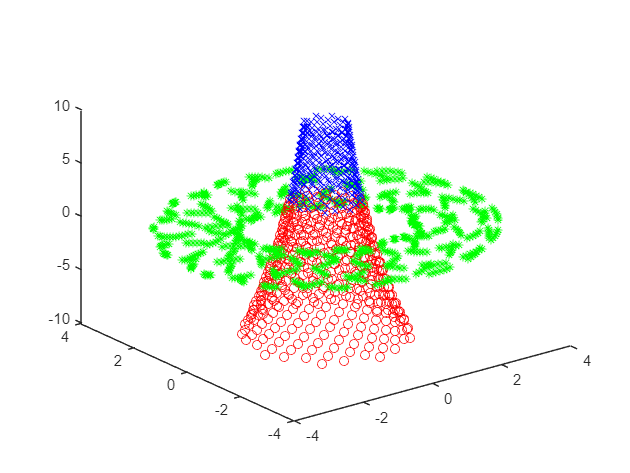

%Plotting the resulting clustered points

figure 
hold on
for i = 1:M
    plot3(Xt(1, idx == i), Xt(2, idx == i),  Xt(3, idx == i), markers(i, :))
end
view(3)

# Exercise 9

Computing the clusters with other clustering methos from library. 

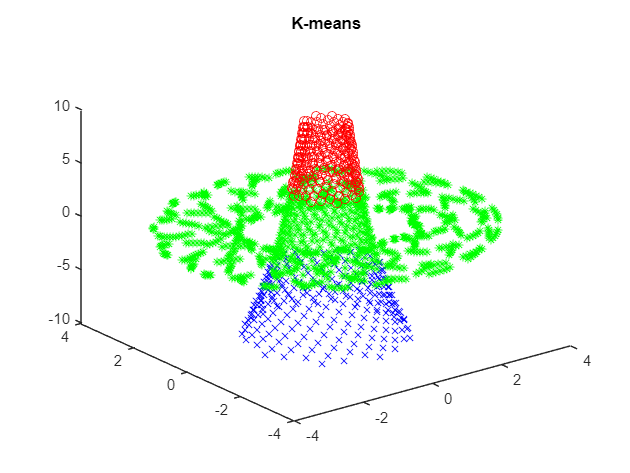

%K-means 

idx_km = kmeans(X, M);

figure
hold on 
for i = 1:M
    plot3(Xt(1, idx_km == i), Xt(2, idx_km == i),  Xt(3, idx_km == i), markers(i, :))
end
title('K-means')
view(3)

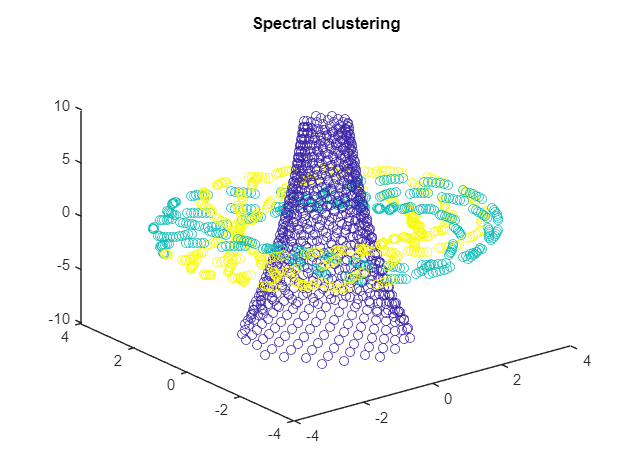

%Spectral clustering 

idx_sc = spectralcluster(X, M, 'SimilarityGraph', 'knn', 'NumNeighbors', k, 'LaplacianNormalization', 'symmetric', 'KNNGraphType', 'mutual'); 
% idx_sc = spectralcluster(X, M, 'SimilarityGraph', 'knn', 'NumNeighbors', k, 'LaplacianNormalization', 'symmetric');

figure
hold on;
scatter3(Xt(1,:),Xt(2,:),Xt(3,:),[], idx_sc);
title('Spectral clustering')
view(3)

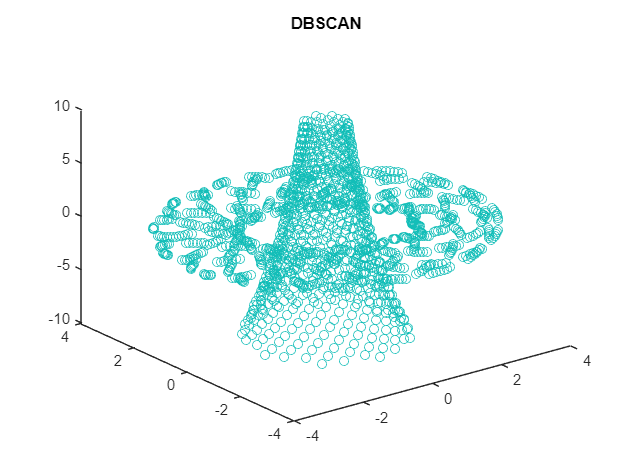


%DBSCAN:

%idx_db = dbscan(X, 0.8, 2);
idx_db = dbscan(X, 1, 2);

figure
hold on           
scatter3(Xt(1,:),Xt(2,:),Xt(3,:), [], idx_db);
title('DBSCAN')
view(3)